FFT

Decimation in time(DIT)

x=[1 2 3 4];
N = length(x);
%bit reversal of input sequence x
x = bitrevorder(x);
S = log2(N);
mid = 1;
%butterfly computation
for stage = 1:S
     for index = 0 : (2^stage) : N-1
         for n = 0:mid-1
             WN = exp(-1j*2*pi*n/(2^stage));
             indx = index + n + 1;
             A = x(indx) + x(indx + mid) * WN;
             B = x(indx) - x(indx + mid) * WN;
             x(indx) = A;
             x(indx+mid) = B;
         end
     end
 mid = mid * 2;
end
y = x'

y =   10.0000 + 0.0000i
  -2.0000 - 2.0000i
  -2.0000 + 0.0000i
  -2.0000 + 2.0000i


Decimation in Frequency(DIF)

x=[1 2 3 4]                                        

x =      1     2     3     4


p=nextpow2(length(x));                                                     
x=[x zeros(1,(2^p)-length(x))];                                             
N=length(x);                                                               
S=log2(N);                                                                 
mid=N/2;                                                                   
for stage=1:S                                                              
    for index=0:(N/(2^(stage-1))):(N-1)                              
        for n=0:(mid-1)                                               
            indx=n+index+1;                                                  
            pow=(2^(stage-1))*n;                                           
            w=exp((-1i)*(2*pi)*pow/N);                                     
            a=x(indx)+x(indx+mid);                                           
            b=(x(indx)-x(indx+mid)).*w;                                      
            x(indx)=a;                                                      
            x(indx+mid)=b;                                                 
        end
    end
mid=mid/2;                                                                
end
y=bitrevorder(x)'        

y =   10.0000 + 0.0000i
  -2.0000 - 2.0000i
  -2.0000 + 0.0000i
  -2.0000 + 2.0000i


2(a)

n=[1 5 6]

n =      1     5     6


d=[1 4 6]

d =      1     4     6


zer=roots(n)

zer =    -3.0000
   -2.0000


pol=roots(d)

pol =   -2.0000 + 1.4142i
  -2.0000 - 1.4142i


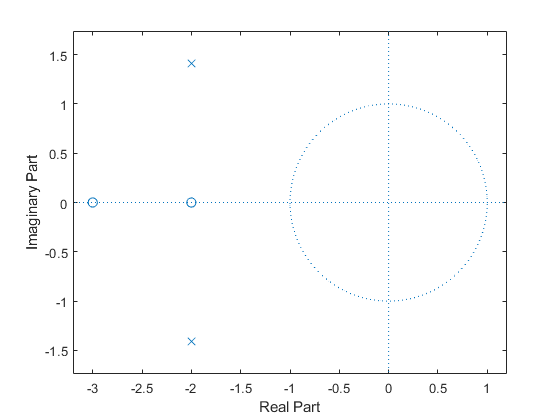


zplane(n,d);


syms z;
t=poly2sym(n,z)

$$t = z^{2}+5\,z+6$$

factor(t, z, 'FactorMode', 'full')

$$ans = \left(\begin{array}{cc} z+3 & z+2 \end{array}\right)$$

r=poly2sym(d,z)

$$r = z^{2}+4\,z+6$$

factor(r, z, 'FactorMode', 'full')

$$ans = \left(\begin{array}{cc} z+2+\sqrt{2}\,\mathrm{i} & z+2-\sqrt{2}\,\mathrm{i} \end{array}\right)$$



ninv=[6 5 1];
dinv=[6 4 1];

syms zinv;
tinv=poly2sym(ninv,zinv)

$$tinv = 6\,{\mathrm{zinv}}^{2}+5\,\mathrm{zinv}+1$$

factor(tinv, zinv, 'FactorMode', 'full')

$$ans = \left(\begin{array}{cc} 2\,\mathrm{zinv}+1 & 3\,\mathrm{zinv}+1 \end{array}\right)$$

rinv=poly2sym(dinv,zinv)

$$rinv = 6\,{\mathrm{zinv}}^{2}+4\,\mathrm{zinv}+1$$

factor(rinv, zinv, 'FactorMode', 'full')

$$ans = \left(\begin{array}{cc} \mathrm{zinv}+\frac{1}{3}+\frac{\sqrt{2}\,\mathrm{i}}{6} & \mathrm{zinv}+\frac{1}{3}-\frac{\sqrt{2}\,\mathrm{i}}{6} \end{array}\right)$$

2(c) 

k=3.9;
z=[0.3 2.5 (-0.2+1i*0.4) (-0.2-1i*0.4)]';
p=[0.5 -0.75 (0.6+j*0.7) (0.6-j*0.7)]';

[b,a]=zp2tf(z,p,k)

b =     3.9000   -9.3600   -0.6630   -1.0140    0.5850


a =     1.0000   -0.9500    0.1750    0.6625   -0.3187


(d)

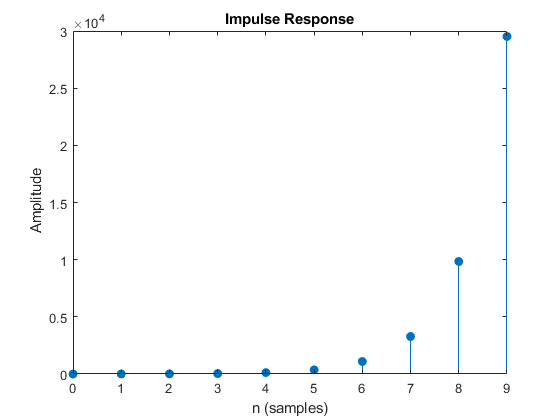

b=[1];
a=[1 -4 3];
impz(b,a,10);

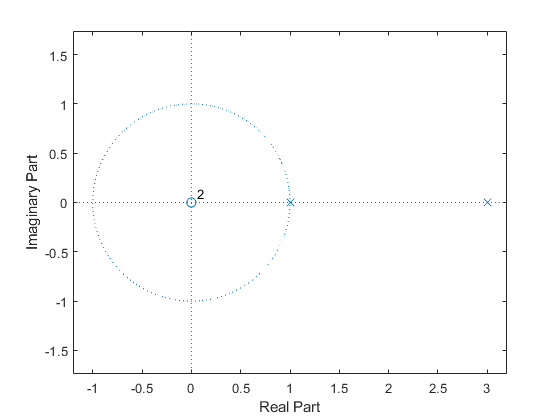

zplane(b,a);


[r,p,k] = residuez(b,a)

r =     1.5000
   -0.5000


p =      3
     1



k =

     []



r=r';
p=p';
closed_form=zeros(1,10);
n=0:9;
for i=1:length(p)
    closed_form=closed_form + r(i)*p(i).^n;
end

closed_form

closed_form = 	1.0e+04 *

    0.0001    0.0004    0.0013    0.0040    0.0121    0.0364    0.1093    0.3280    0.9841    2.9524


(e)

b=[1];
a=[1 -4 3];
impz(b,a,10);

zplane(b,a);


[r,p,k] = residuez(b,a);

[bn,ad]=residuez(r,p,k)

bn =     1.0000    0.0000


ad =      1    -4     3
